close all;clear all;clc;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


G = (1-s)*exp(-s)/((12*s+1)*(3*s+1)*(0.2*s + 1)*(0.05*s+1))

G =
 
                                 -s + 1
  exp(-1*s) * ---------------------------------------------
              0.36 s^4 + 9.15 s^3 + 39.76 s^2 + 15.25 s + 1
 
Continuous-time transfer function.
Model Properties


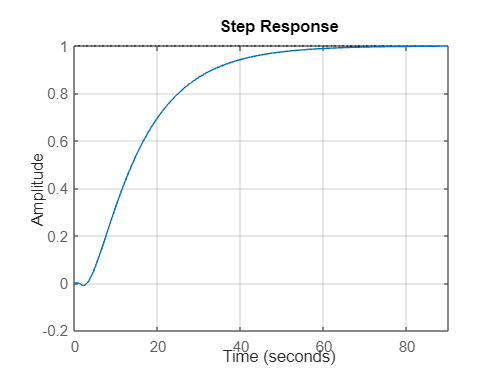

t = 0:0.1:80;
[y,~] = step(G,t);
step(G)
grid

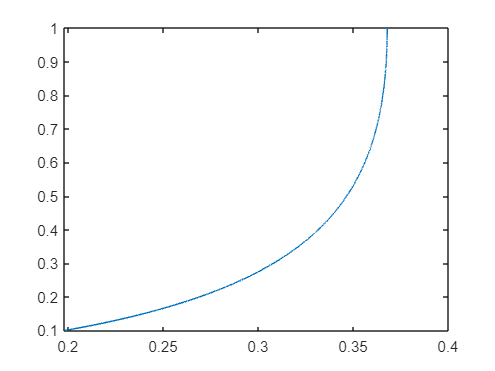

%---
eta = linspace(0.1,1,10000);
lambda = (log(eta)./(eta-1)).*exp(-log(eta)./(eta-1));
plot(lambda,eta)

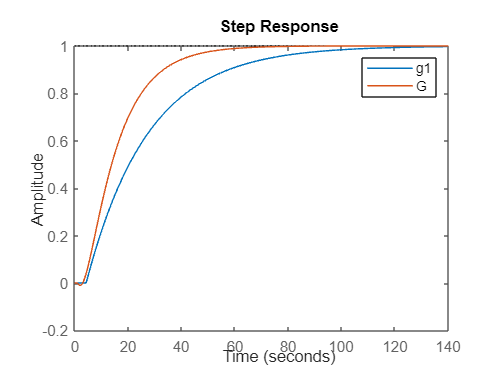

%ب و ج
g1 = exp(-4.3*s)/(23.2*s+1);
g2 = exp(-4.3*s)/(12.76*s+1) ;
g3 = exp(-4.3*s)/(11.43*s+1) ;
g4 = exp(-4.3*s)/(18*s+1) ;
g5 = exp(-2.86*s)/((2.52*s+1)*(12.62*s+1)) ;
g6 = exp(-4.3*s)/((6.185*s+1)^2 );
[y1,~] = step(g1,t);
step(g1,G)
legend("g1","G")

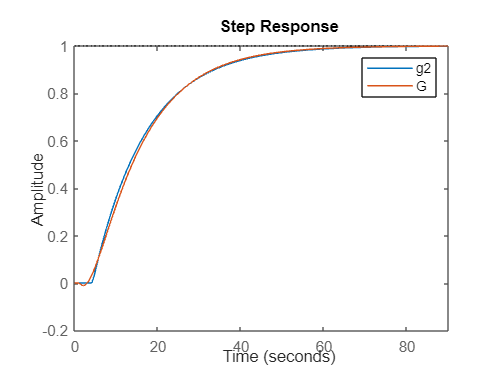

[y2,~] = step(g2,t);
step(g2,G)
legend("g2","G")

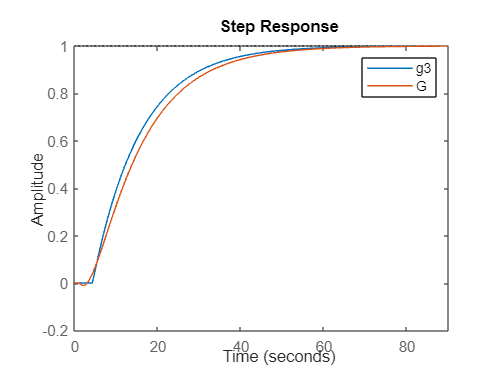

[y3,~] = step(g3,t);
step(g3,G)
legend("g3","G")

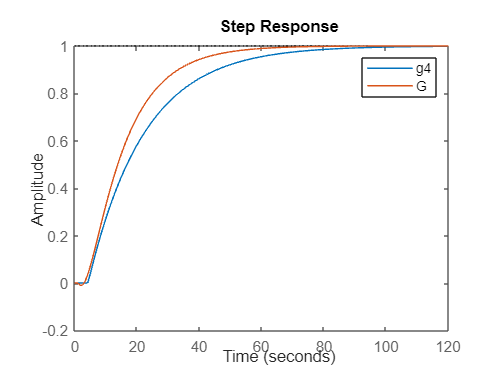

[y4,~] = step(g4,t);
step(g4,G)
legend("g4","G")

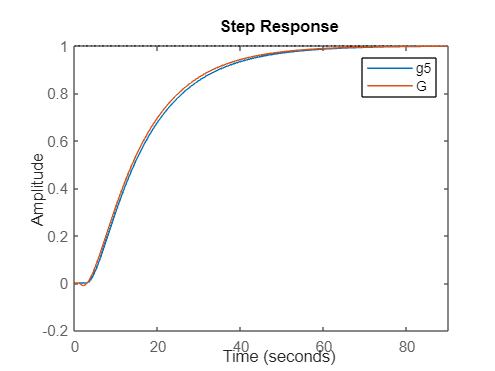

[y5,~] = step(g5,t);
step(g5,G)
legend("g5","G")

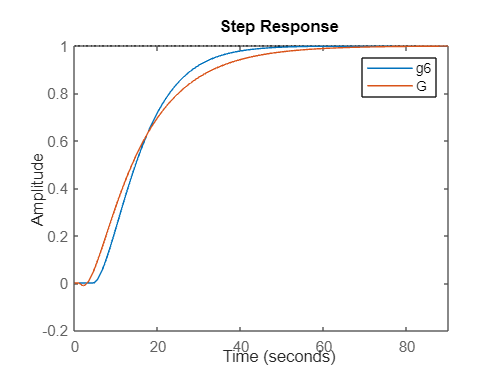

[y6,~] = step(g6,t);
step(g6,G)
legend("g6","G")


err1 = MSE(t.',y,y1)

err1 = 0.0178

err2 = MSE(t.',y,y2)

err2 = 1.2700e-04

err3 = MSE(t.',y,y3)

err3 = 8.4876e-04

err4 = MSE(t.',y,y4)

err4 = 0.0050

err5 = MSE(t.',y,y5)

err5 = 1.4793e-04

err6 = MSE(t.',y,y6)

err6 = 0.0015

function e = MSE(T,Y,Y_test)
    e = 0 ;
    for i = 1:length(T)
        e = e + (Y(i)-Y_test(i))^2;
    end
    e = e/length(T);
end